org = Org;
org.load_definitions;

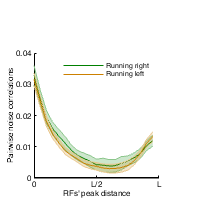

figure;
ncd_r = cell2mat(org.fetch('nc_by_dist_r')');
r_h = serrorbar(0:19, mean(ncd_r), sem(ncd_r).*1.96, 'lineprops', {'-', 'Color', [0 0.5 0]});
hold on;
ncd_l = cell2mat(org.fetch('nc_by_dist_l')');
l_h = serrorbar(0:19, mean(ncd_l), sem(ncd_l).*1.96, 'lineprops', {'-', 'Color', [0.8 0.5 0]});

l_ = refline(0,0); l_.Color = 'k';
xlabel 'RFs'' peak distance'
ylabel 'Pairwise noise correlations'
legend([r_h.mainLine l_h.mainLine], 'Running right', 'Running left');
legend boxoff

figure_format([1.3 1.3]);
set(gca, 'XTick', [0 10 20]);
set(gca, 'XTickLabel', {'0', 'L/2', 'L'});
Utils.printto('events_figs/noise_corr_by_distance', 'nc_dist.pdf');

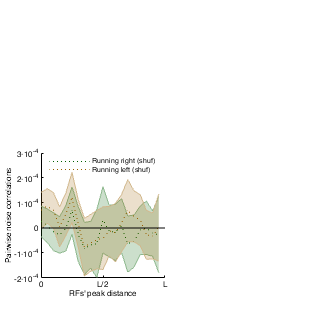

figure;

ncd_r = cell2mat(org.fetch('nc_by_dist_r_shuf')');
r_h = serrorbar(0:19, mean(ncd_r), sem(ncd_r).*1.96, 'lineprops', {':', 'Color', [0 0.5 0] * 0.75});
hold on;
ncd_l = cell2mat(org.fetch('nc_by_dist_l_shuf')');
l_h = serrorbar(0:19, mean(ncd_l), sem(ncd_l).*1.96, 'lineprops', {':', 'Color', [0.8 0.5 0] * 0.75});

l_ = refline(0,0); l_.Color = 'k';
xlabel 'RFs'' peak distance'
ylabel 'Pairwise noise correlations'

legend([r_h.mainLine l_h.mainLine], 'Running right (shuf)', 'Running left (shuf)');
legend boxoff
legend location best

set(gca, 'XTick', [0 10 20]);
set(gca, 'XTickLabel', {'0', 'L/2', 'L'});

figure_format([1.3 1.3], 'fig_factor', 2.5);
Utils.fix_exponent(gca, 'y', 0);
Utils.printto('events_figs/noise_corr_by_distance', 'nc_dist_shuf.pdf');